## **Fuselage Loads**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Initial constant**

g = 9.80665;       % Standard acceleration of gravity (m/s^2)
L_fuselage = 69.1; % Fuselage length (m)

**0.2 Read data**

Case = load('Case.mat');

Sym = Case.Sym;
Sym_neg = Case.Sym_neg;
Landing = Case.Landing;
OEI = Case.OEI;
dx  = Sym(1, 2) - Sym(1, 1); % Spatial discretization step (m）

### **1 Positive Symmetric Loading Case**

**1.1 Inertia Load**

Sum the inertia load + spar reaction force

Load_Sym1 = -Sym(2, :) + Sym(3, :) + Sym(4, :);

Calculate the shear force

SF_Sym1 = cumtrapz(Sym(1, :), Load_Sym1);

Calculate discretised bending moment

BM_Sym1 = cumtrapz(Sym(1, :), SF_Sym1);

Eliminate small error

% SF_Sym1(end) = 0;
% BM_Sym1(end) = 0;

Plot the result

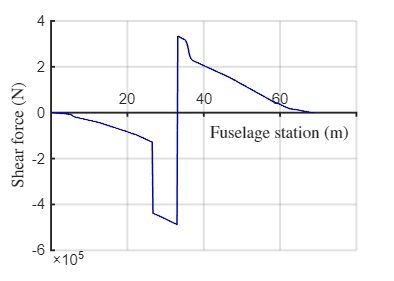

figure(1)

clf;

plot(Sym(1, :), SF_Sym1, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

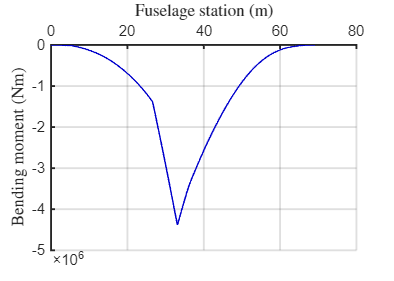

figure(2)

clf;

plot(Sym(1, :), BM_Sym1, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

**1.2 Aero Load**

Sum the spar reaction force and aero force

Load_Sym2 = Sym(5, :) + Sym(6, :) + Sym(7, :);

Calculate the shear force

SF_Sym2 = cumtrapz(Sym(1, :), Load_Sym2);

Calculate discretised bending moment

BM_OEI2 = cumtrapz(Sym(1, :), SF_Sym2);

Eliminate small error

% SF_Sym2(end) = 0;
% BM_Sym2(end) = 0;

Plot the result

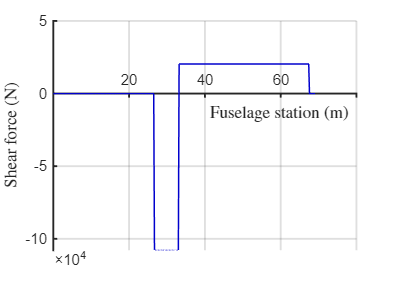

figure(3)

clf;

plot(Sym(1, :), SF_Sym2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

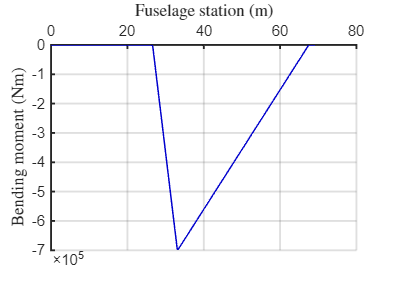

figure(4)

clf;

plot(Sym(1, :), BM_OEI2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

**1.3 Superposition**

SF_Sym = SF_Sym1 + SF_Sym2;
BM_Sym = BM_Sym1 + BM_OEI2;

Eliminate small error

SF_Sym(end) = 0;
BM_Sym(end) = 0;

Plot the result

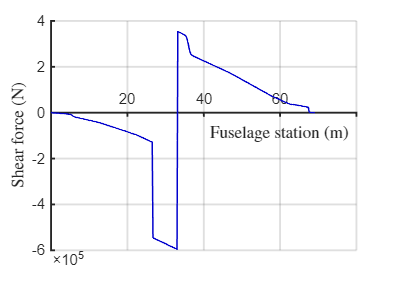

figure(5)

clf;

plot(Sym(1, :), SF_Sym, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

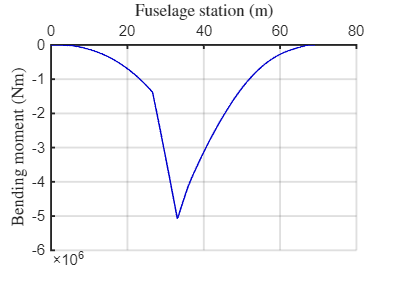

figure(6)

clf;

plot(Sym(1, :), BM_Sym, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

### **2 Negative Symmetric Loading Case**

**2.1 Inertia Load**

Sum the inertia load + spar reaction force

Load_Sym_neg1 = -Sym_neg(2, :) + Sym_neg(3, :) + Sym_neg(4, :);

Calculate the shear force

SF_Sym_neg1 = cumtrapz(Sym(1, :), Load_Sym_neg1);

Calculate discretised bending moment

BM_Sym_neg1 = cumtrapz(Sym(1, :), SF_Sym_neg1);

Eliminate small error

% SF_Sym_neg1(end) = 0;
% BM_Sym_neg1(end) = 0;

Plot the results

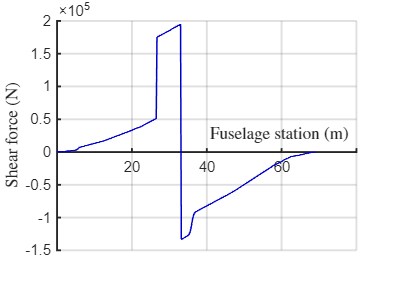

figure(7)
clf;
plot(Sym_neg(1, :), SF_Sym_neg1, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

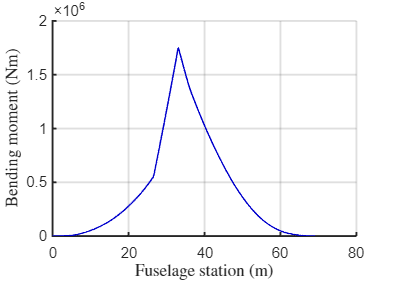


figure(8)
clf;
plot(Sym_neg(1, :), BM_Sym_neg1, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

**2.2 Aero Load**

Sum the spar reaction force and aero force

Load_Sym_neg2 = Sym_neg(5, :) + Sym_neg(6, :) + Sym_neg(7, :);

Calculate the shear force

SF_Sym_neg2 = cumtrapz(Sym(1, :), Load_Sym_neg2);

Calculate discretised bending moment

BM_Sym_neg2 = cumtrapz(Sym(1, :), SF_Sym_neg2);

Eliminate small error

% SF_Sym_neg2(end) = 0;
% BM_Sym_neg2(end) = 0;

Plot the results

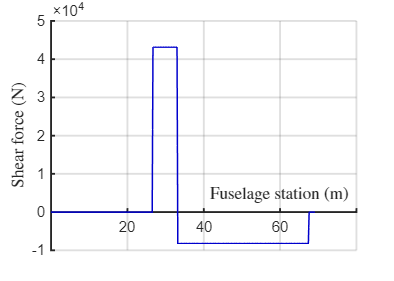

figure(9)
clf;
plot(Sym_neg(1, :), SF_Sym_neg2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

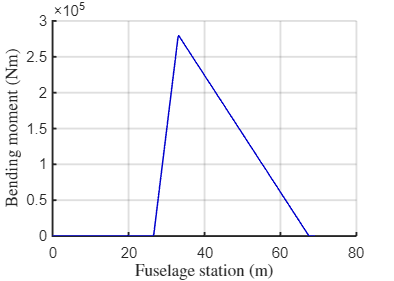


figure(10)
clf;
plot(Sym_neg(1, :), BM_Sym_neg2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

**2.3 Superposition**

SF_Sym_neg = SF_Sym_neg1 + SF_Sym_neg2;
BM_Sym_neg = BM_Sym_neg1 + BM_Sym_neg2;

Eliminate small error

SF_Sym_neg(end) = 0;
BM_Sym_neg(end) = 0;

Plot the result

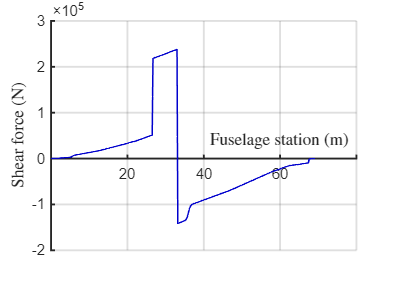

figure(11)
clf;
plot(Sym_neg(1, :), SF_Sym_neg, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

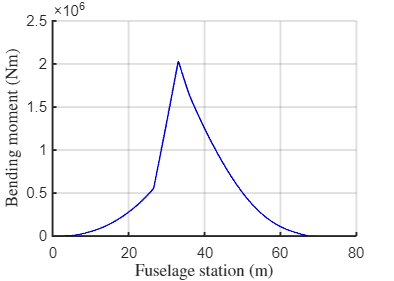

figure(12)
clf;
plot(Sym_neg(1, :), BM_Sym_neg, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

### **3 Nose-Gear-Off Case**

Sum the inertia load + gear reaction force

Load_Landing = -Landing(2, :) + Landing(3, :) + Landing(4, :);

Calculate the shear force

SF_Landing = cumtrapz(Sym(1, :), Load_Landing);

Calculate discretised bending moment

BM_Landing = cumtrapz(Sym(1, :), SF_Landing);

Eliminate small error

SF_Landing(end) = 0;
BM_Landing(end) = 0;

Plot the results

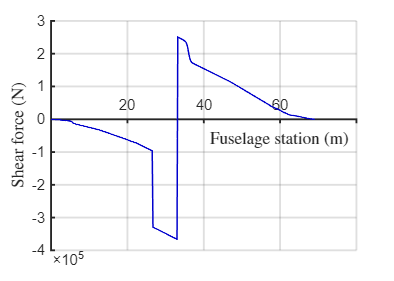

figure(13)
clf;
plot(Landing(1, :), SF_Landing, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

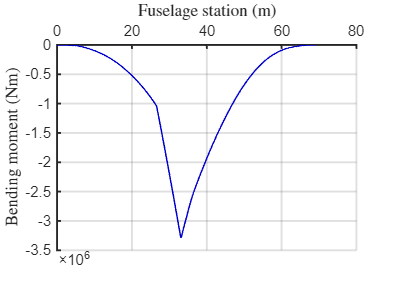


figure(14)
clf;
plot(Landing(1, :), BM_Landing, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1);
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');
set(gca, 'FontSize', 10);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';
grid on;
set(gcf, 'Position', [0 0 350 250]);

### **4 OEI Case**

**4.1 Inertia Load**

Sum the inertia load + spar reaction force

Load_OEI1 = -OEI(2, :) + OEI(3, :) + OEI(4, :);

Calculate the shear force

SF_OEI1 = cumtrapz(Sym(1, :), Load_OEI1);

Calculate discretised bending moment

BM_OEI1 = cumtrapz(Sym(1, :), SF_OEI1);

Eliminate small error

% SF_Sym1(end) = 0;
% BM_Sym1(end) = 0;

Plot the result

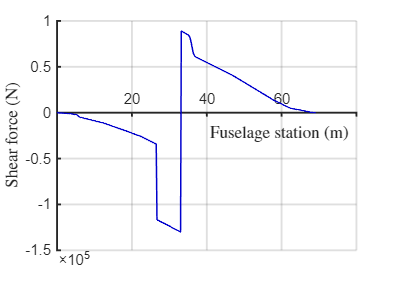

figure(15)

clf;

plot(Sym(1, :), SF_OEI1, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

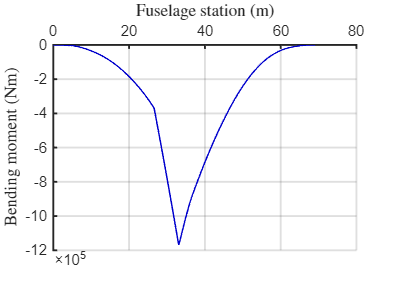

figure(16)

clf;

plot(Sym(1, :), BM_OEI1, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

**4.2 Aero Load**

Sum the spar reaction force and aero force

Load_OEI2 = OEI(5, :) + OEI(6, :) + OEI(7, :);

Calculate the shear force

SF_OEI2 = cumtrapz(Sym(1, :), Load_OEI2);

Calculate discretised bending moment

BM_OEI2 = cumtrapz(Sym(1, :), SF_OEI2);

Eliminate small error

% SF_Sym2(end) = 0;
% BM_Sym2(end) = 0;

Plot the result

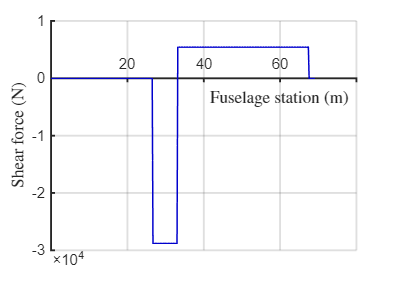

figure(17)

clf;

plot(Sym(1, :), SF_OEI2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

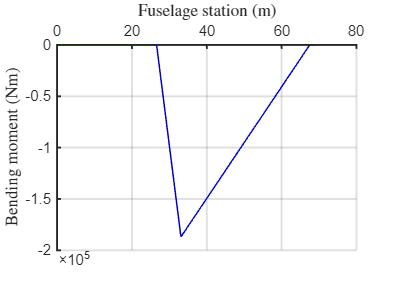

figure(18)

clf;

plot(Sym(1, :), BM_OEI2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

**4.3 Superposition**

SF_OEI = SF_OEI1 + SF_OEI2;
BM_OEI = BM_OEI1 + BM_OEI2;

Eliminate small error

SF_OEI(end) = 0;
BM_OEI(end) = 0;

Plot the result

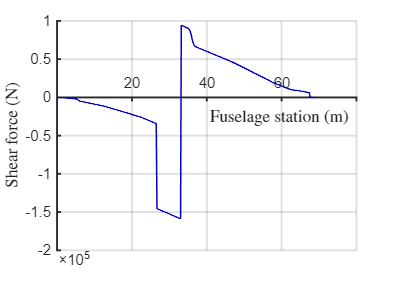

figure(19)

clf;

plot(Sym(1, :), SF_OEI, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

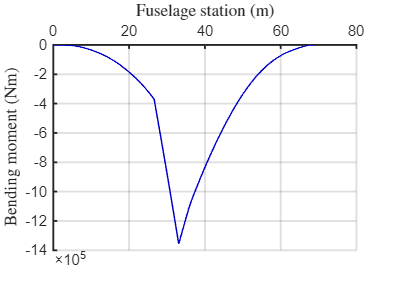

figure(20)

clf;

plot(Sym(1, :), BM_OEI, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)

% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 350 250]);

### **5 Plotting**

**5.1 Shear force**

figure(21)

clf;

plot(Sym(1, :), SF_Sym, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot(Sym(1, :), SF_Sym_neg, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot(Sym(1, :), SF_Landing, '-.', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold on
plot(Sym(1, :), SF_OEI, ':', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.25)
hold off

txt1 = 'S_{max} = 3.54x10^5';
txt2 = 'S_{min} = -5.95x10^5';

text(0, 0, txt1, 'Color', [0/255 0/255 205/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)

% Legends
legend("Symmetric (n_{ult}=3.5)","Symmetric (n_{ult,neg}=-1.5)", "Landing (n=2.82)", "OEI (n=1)", "best", 'NumColumns', 1, FontSize = 9)

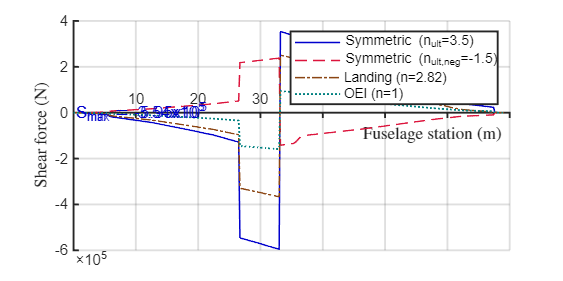


% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Shear force (N)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;

% Set figure size
set(gcf, 'Position', [0 0 500 250]);

**5.2 Bending Moment**

figure(21)

clf;

plot(Sym(1, :), BM_Sym, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1)
hold on
plot(Sym(1, :), BM_Sym_neg, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1)
hold on
plot(Sym(1, :), BM_Landing, '-.', 'Color', [139/255 69/255 19/255], 'LineWidth', 1)
hold on
plot(Sym(1, :), BM_OEI, ':', 'Color', [0/255 128/255 128/255], 'LineWidth', 1.25)
hold off

txt1 = 'M_{max} = 2.03x10^6';
txt2 = 'M_{min} = -5.07x10^6';

text(0, 0, txt1, 'Color', [220/255 20/255 60/255], 'FontSize', 11)
text(0, 0, txt2, 'Color', [0/255 0/255 205/255], 'FontSize', 11)


% Legends
legend("Symmetric (n_{ult}=3.5)","Symmetric (n_{ult,neg}=-1.5)", "Landing (n=2.82)", "OEI (n=1)", "best", 'NumColumns', 1, FontSize = 9)

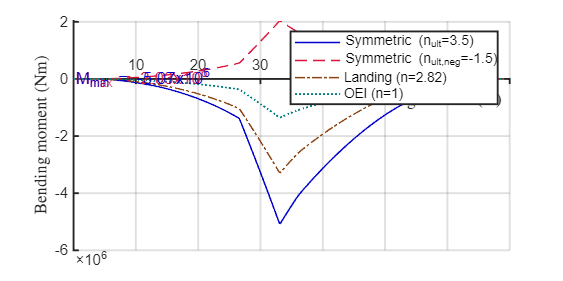


% Axis labels with LaTeX font
xlabel('Fuselage station (m)', 'Interpreter', 'latex');
ylabel('Bending moment (Nm)', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 10); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
grid on;


% Set figure size
set(gcf, 'Position', [0 0 500 250]);